# Import Data

clear all
format shortG

filename = 'log.txt';
% remember: cd 'C:\Users\marti\OneDrive - Danmarks Tekniske Universitet\DTU\2-rotor drone Bachelor'
%filename = 'logFreeFlight10sec.txt';                %shit
%filename = 'logFF20sec10til20sec.txt';              %shit
%filename = 'logFreeFlight10secRamteJord17_27.txt';  %shit
%filename = 'logFreeFlight15sec.txt';                %Usable
%filename = 'logYAWprev.txt'
filename = 'log Pitch forward.txt';
filename='log Pitch backwards.txt'

filename = 'log Pitch backwards.txt'


cd('C:\Users\User\OneDrive\DTU\DTU 4-2-2020\DTU\6. semester\bachelor projekt\Flight data')
% 1     Time (ms)
% 2     Arm state (init, disarmed, armed, fail)
% 3     Flight state (on ground, starting, flight, landing)
% 4     Pitch angle ref (deg)
% 5     Pitch angle rate ref (deg/s)
% 6     Pitch angle rate (gyro) (deg/s)
% 7     Pitch value to mixer o/oo
% 8     Pitch angle (deg)

rawimport = importdata(filename);
rawdata = rawimport.data;

t = rawdata(:,1)./1000; % 1     Time (s)
arm_state = rawdata(:,2); % 2     Arm state (init, disarmed, armed, fail)
flight_state = rawdata(:,3); % 3     Flight state (on ground, starting, flight, landing)
ang_ref = rawdata(:,4); % 4     Height ref (thrust ref)
ang_rate_ref = rawdata(:,5); % 5     Roll ref (deg)
ang_rate = rawdata(:,6); % 6     Pitch ref (deg)
value_mixer = rawdata(:,7); % 7     Yaw ref (deg/s)
ang = rawdata(:,8); % 8     Height value to mixer (thrust ref) o/oo
%{
r_mixer = rawdata(:,9); % 9     Roll value to mixer o/oo
p_mixer = rawdata(:,10); % 10    Pitch value to mixer o/oo
y_mixer = rawdata(:,11); % 11    Yaw value to mixer o/oo
h_pos = rawdata(:,12); % 12    Height position (m) filtered 
r_pos = rawdata(:,13); % 13    Roll angle (deg)
p_pos = rawdata(:,14); % 14    Pitch angle (deg)
y_vel = rawdata(:,15); % 15    Yaw velocity (deg/s)
h_vel = rawdata(:,16); % 16    Height velocity (m/s) does'nt work after


%Sorting all according to time t:
[t, idx] = sort(t);
r_pos = r_pos(idx);
r_ref = r_ref(idx);
p_pos = p_pos(idx);
p_ref = p_ref(idx);
y_vel = y_vel(idx);
y_ref = y_ref(idx);
h_pos = h_pos(idx);
h_vel = h_vel(idx);
h_ref = h_ref(idx);
p_mixer=p_mixer(idx);
r_mixer=r_mixer(idx);
y_mixer=y_mixer(idx);
%} 

## Pitch Velocity

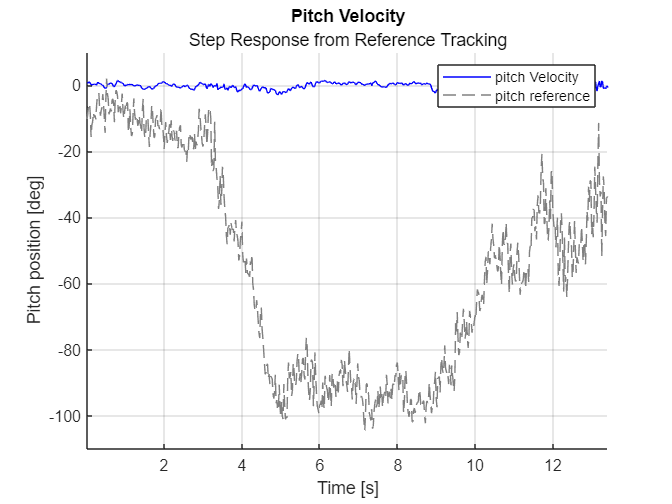



clf
hold on
plot_meas = plot(t,ang_rate, 'DisplayName', 'pitch Velocity');
plot_ref = plot(t,ang_rate_ref, '--','DisplayName', 'pitch reference');
%plot_mixer = plot(t,value_mixer, '--','DisplayName', 'pitch reference');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Pitch Velocity", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
hold off

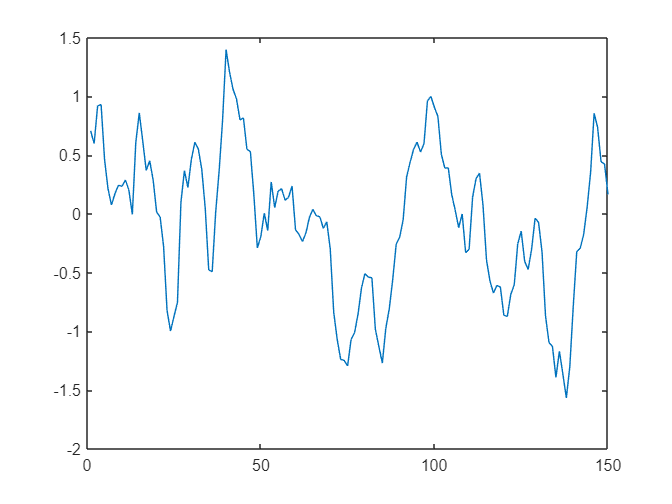

plot(ang_rate(t<3))

var(ang_rate(t<3))

ans =       0.40562


## Pitch Position

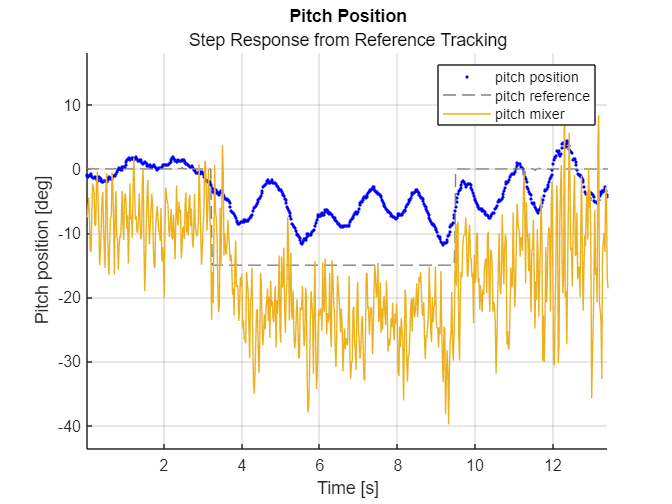


clf
hold on
plot_meas = plot(t,movmean(ang + value_mixer.*0.0505,20),'.', 'DisplayName', 'pitch position');
plot_ref = plot(t,ang_ref, '--','DisplayName', 'pitch reference');
plot_mixer = plot(t,value_mixer./10,'DisplayName', 'pitch mixer');
plot_meas.Color = [0, 0, 1];
plot_ref.Color = [0.5, 0.5, 0.5];
title("Pitch Position", "Step Response from Reference Tracking")
xlabel('Time [s]');
ylabel('Pitch position [deg]') 
grid on
%ylim([-60, 60])
%xlim([-60, 60])
xlim tight
ylim padded
lgd = legend;
hold off